# Multishot camera

## Scenario setup

% Start the simulator.
beamng =  py.beamngpy.BeamNGpy('localhost', int32(64256));
% beamng = py.beamngpy.BeamNGpy('localhost', int32(64256), home='/path/to/BeamNG.drive');

beamng.open();

% Create a vehicle.
vehicle = py.beamngpy.Vehicle('ego_vehicle', ...
    pyargs('model', 'etki', 'licence', 'Matlab', 'color', 'Green'));

% Create a scenario.
scenario = py.beamngpy.Scenario('smallgrid', 'multishot', ...
    pyargs('description', 'Demo of the camera sensor used like a multishot camera'));
scenario.add_vehicle(vehicle);
scenario.make(beamng);
beamng.load_scenario(scenario);

## Run simulation

beamng.start_scenario();

% Create a default camera sensor, attached to the vehicle.
cam_width = 1280;
cam_height = 720;
camera = py.beamngpy.sensors.Camera('camera1', beamng, vehicle, ...
    pyargs('resolution', py.tuple({int32(cam_width), int32(cam_height)})));

% Compute the center of the vehicle bounding box, to give us a point at which to focus the camera.
bbox = vehicle.get_bbox();
rbl = double(py.numpy.array(bbox{'rear_bottom_left'}));
fbr = double(py.numpy.array(bbox{'front_bottom_right'}));
rtl = double(py.numpy.array(bbox{'rear_top_left'}));
center = rbl + ((fbr - rbl) / 2) + ((rtl - rbl) / 2);

% An offset to move center back a bit to get more of the vehicle.
center(1) = center(1) - 2;                                     
% An offset to move the camera a few metres in front of the center.
pos_offset = center + [5, -2, 0];                                 

% Compute all the angles we will need, in radians.
variations = [- 30 * pi/360, 0.0, 20 * pi/360];

ctr = 1;
cam_images = cell(1, 9);
for h = variations .* 2
    for v = variations
        rot_x = cos(h) * pos_offset(1) - sin(h) * pos_offset(2);
        rot_y = sin(h) * pos_offset(1) + cos(h) * pos_offset(2);
        rot_z = sin(v) * rot_y + cos(v) * pos_offset(3);
        new_pos = [rot_x, rot_y, rot_z];
        % Set the camera position for this image.
        camera.set_position(new_pos);                               
        dir = center - new_pos;
        % Set the camera direction for this image.
        camera.set_direction([dir(1), dir(2), dir(3)]);             
         % A slight delay to allow the automated camera to get fresh readings.
        pause(0.3);                                                
        % Get the latest image data from the camera.      
        data = camera.poll();                                       
        % The colour image. We can use {'annotation'} or {'depth'} instead.     
        cam_images{ctr} = double(py.numpy.array(data{'colour'}));   
        ctr = ctr + 1;
    end
end

% Tidy up and close the simulation.
camera.remove();
beamng.close();

## Plot results

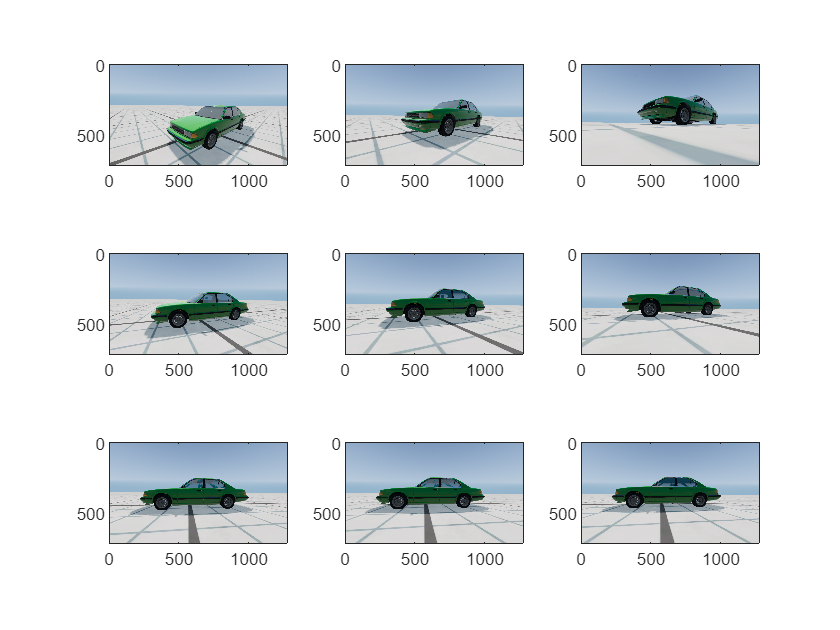

% Plot all the images.
ctr = 1;
for x = 1:3
    for y = 1:3
        subplot(3, 3, ctr);
        colour_RGBA = double(py.numpy.array(cam_images{ctr}));
        colour_RGB = colour_RGBA(:, :, 1:3) / 256;
        image(colour_RGB);
        ctr = ctr + 1;
        axis equal
        xlim([0 cam_width])
        ylim([0 cam_height])
    end
end